%2.21
syms('x','real');syms('A','positive');syms('a','positive')

psi(x) = A*exp(-a*x^2)
Asol=solve(int(psi(x)^2,x,-Inf,Inf)==1,A)
psi(x)=subs(psi(x),A,Asol);

syms('k','real')
phi(k)=simplify(1/(sqrt(2*sym(pi))) * int(exp(-1i*k*x)*psi(x),x,-Inf,Inf))
sympref("FourierParameters",[1/(sqrt(2*sym(pi))),-1])
syms('t','positive');syms('h','positive');syms('m','positive')
%Psi(x,t) = ifourier(phi(k)*exp(-1i*h*k^2*t/(2*m)), k, x)
%Psi(x,t)= 1/sqrt(2*sym(pi))*int(phi(k)*exp((1i*k) * (x - (h*k*t)/(2*m))),k,-Inf,Inf)
Psi(x,t) = simplify(1/sqrt(2*sym(pi)) * 1/((2*a*sym(pi))^(1/4)) * int(exp(1i*k*x - k^2*(1/(4*a) + 1i*h*t/(2*m))),k,-Inf,Inf))


%w= sqrt(a/ (1 + (2*h*a*t / m)^2))
Psi2(x,t)=simplify(conj(Psi(x,t))*Psi(x,t))
x_plot = linspace(-5,5,50)
%hand derived:
syms('w','positive')
Psi2w=sqrt(2/sym(pi))*w*exp(-2* w^2 * x^2)


Psi2_0(x)= subs(Psi2,a,1)
Psi2_0(x)= subs(Psi2_0,sym(pi),pi)
Psi2_t0(x)= subs(Psi2_0,t,0)
plot(x_plot,Psi2_t0(x_plot))
title('t=0')

Psi2_t10(x)= subs(Psi2_0,t,10)
Psi2_t10(x)= subs(Psi2_t10,m,1)
Psi2_t10(x)= subs(Psi2_t10,h,1)
plot(x_plot,Psi2_t10(x_plot))
title('t=10')
%As t increases, the width of the gaussian increases, and the amplitude
%decreases, meaning the probability is more evenly distributed away from 0 
%at later times

exp_x= int(conj(Psi)*x*Psi,x,-Inf,Inf)
exp_x2=simplify(int(conj(Psi)*x^2*Psi,x,-Inf,Inf))
exp_p=int(conj(Psi)*(h/1i)*diff(Psi,x),x,-Inf,Inf)
exp_p2=simplify(int(conj(Psi)*(h/1i)^2*diff(Psi,x,2),x,-Inf,Inf))

sigma_x = sqrt(exp_x2);
sigma_p = sqrt(exp_p2);
uncertainty=sigma_x*sigma_p

uncertainty=subs(uncertainty,a,1);
uncertainty=subs(uncertainty,h,1);
uncertainty=subs(uncertainty,m,1);
uncertainty=subs(uncertainty,t,0);

simplify(uncertainty) >= 1/2
%true and it increases for t>0 so its true for all t

%%2.27
clf; close all
syms('a','positive')
alpha = sym('alpha', 'positive');
syms('x', 'real');
syms('E', 'real');
assume(E<0)
syms('m','positive');
syms('h','positive')
syms('k','positive')
syms('A','positive')
syms('C','positive')

E0=solve(k==sqrt(-2*m*E/h^2),E)

%% even state
psi_left=A*exp(k*x)
psi_middle=C*(exp(k*x) + exp(-k*x))
psi_right=A*exp(-k*x)

cont=subs(psi_middle,x,a)==subs(psi_right,x,a);
Asol=solve(cont,A)
jump=subs(diff(psi_right,x),x,a)-subs(diff(psi_middle,x),x,a)==-2*m*alpha/h^2*subs(psi_right,x,a);
jump=subs(jump,A,Asol);
alpha_even=simplify(solve(jump,alpha))      % k = (m*alpha/h^2)(1+exp(-2ka))

psi_left_e=subs(psi_left,A,Asol);
psi_right_e=subs(psi_right,A,Asol);
psi_middle_e=psi_middle;

%% odd state
psi_left=-A*exp(k*x)
psi_middle=C*(exp(k*x) - exp(-k*x))
psi_right=A*exp(-k*x)

cont=subs(psi_middle,x,a)==subs(psi_right,x,a);
Asol=solve(cont,A)
jump=subs(diff(psi_right,x),x,a)-subs(diff(psi_middle,x),x,a)==-2*m*alpha/h^2*subs(psi_right,x,a);
jump=subs(jump,A,Asol);
alpha_odd=simplify(solve(jump,alpha))       % k = (m*alpha/h^2)(1-exp(-2ka))

psi_left_o=subs(psi_left,A,Asol);
psi_right_o=subs(psi_right,A,Asol);
psi_middle_o=psi_middle;

vals=[h m a];
nums=[1 1 1];
a=1
    keven=vpasolve(subs(alpha_even,vals,nums)==a,k,[0 20])
    kodd=vpasolve(subs(alpha_odd,vals,nums)==a,k,[1e-6 20])
    Eeven=subs(E0,[k vals],[keven nums])

    Eodd=subs(E0,[k vals],[kodd nums])


a=1/4
    keven=vpasolve(subs(alpha_even,vals,nums)==a,k,[0 20])
    kodd=vpasolve(subs(alpha_odd,vals,nums)==a,k,[1e-6 20])
    Eeven=subs(E0,[k vals],[keven nums])

    %Eodd=subs(E0,[k vals],[kodd nums])

%%2.29

clf; close all
syms('a','positive')
syms('x', 'real');
syms('E', 'real');
assume(E<0)
syms('m','positive');
syms('h','positive')
syms('V0','positive')
syms('k','positive')
syms('l','positive')
syms('D','positive')
syms('F','positive')

E0=solve(k==sqrt(-2*m*E/h^2),E)

$$E0 = -\frac{h^{2}\,k^{2}}{2\,m}$$


%% odd state
psi_left=-F*exp(k*x)               

$$psi\_left = -F\,{\mathrm{e}}^{k\,x}$$

psi_middle=D*sin(l*x)              

$$psi\_middle = \text{D}\,\sin\left(l\,x\right)$$

psi_right=F*exp(-k*x)               

$$psi\_right = F\,{\mathrm{e}}^{-k\,x}$$


cont=subs(psi_middle,x,a)==subs(psi_right,x,a);
Fsol=solve(cont,F)

$$Fsol = \text{D}\,{\mathrm{e}}^{a\,k}\,\sin\left(a\,l\right)$$

jump=subs(diff(psi_middle,x),x,a)==subs(diff(psi_right,x),x,a);
jump=subs(jump,F,Fsol);
jump=simplify(jump)                 

$$jump = l\,\cos\left(a\,l\right)+k\,\sin\left(a\,l\right)=0$$


% z0=(a/h)*sqrt(2*m*V0), k*a = sqrt(z0^2-z^2)
syms('z','positive')
syms('z0','positive')
odd_eq=-cot(z)==sqrt((z0/z)^2-1)  

$$odd\_eq = -\cot\left(z\right)=\sqrt{\frac{{z_{0}}^{2}}{z^{2}}-1}$$

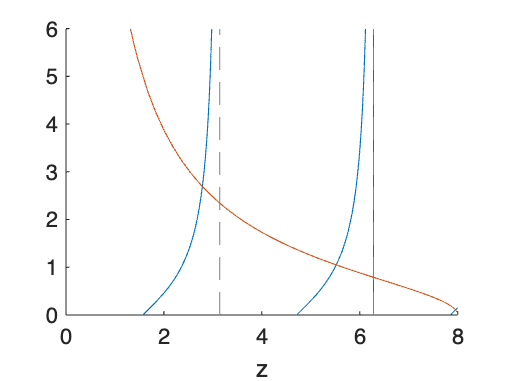

zroots =     2.7859    5.5214    7.9573


EoverV0 =    -0.8787   -0.5237   -0.0106


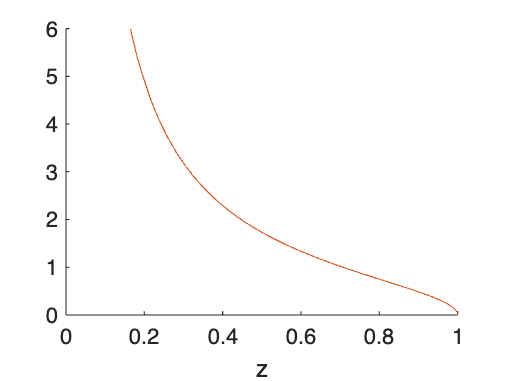


zroots =

     []




EoverV0 =

     []




for z0v=[8 1]
    figure
    hold on
    fplot(-cot(z),[0.01 z0v])
    fplot(sqrt((z0v/z)^2-1),[0.01 z0v])
    ylim([0 6])
    xlabel('z')

    zroots=[];
    for n=1:floor(2*z0v/pi)
        lo=(2*n-1)*pi/2+1e-6;     
        hi=min(n*pi,z0v)-1e-6;
        g=subs(-cot(z)-sqrt((z0/z)^2-1),z0,z0v);
        if hi>lo && double(subs(g,z,lo))*double(subs(g,z,hi))<0
            zroots(end+1)=double(vpasolve(g==0,z,[lo hi]));
        end
    end
zroots
EoverV0=(zroots/z0v).^2-1 

end

% 
% %% limiting cases
% % wide, deep well: z0 -> inf, intersections at z = n*pi
% % shallow, narrow well: first odd state needs z0 > pi/2
% %therefore there is not always a odd bound state


syms('x','real')

syms('V0','positive')
syms('k','positive')